     7



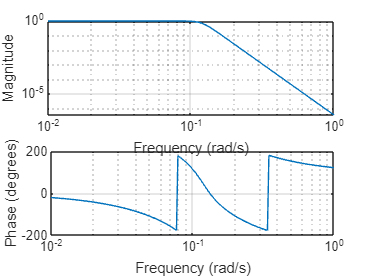

%Program for butterworth and chebyschev:
a=input('Enter the type of filter(1-Butterworth/2-Chebyshev):');
wp=input('Enter the passband frequency:');
ws=input('Enter the stopband frequency:');
rp=input('Enter the passband attenuation:');
rs=input('Enter the stopband attenuation:');
nq=input('Enter the nyquist rate:');
type=input('low/high/stop/bandpass:');
wp=wp/nq;
ws=ws/nq;
switch a
case 1
 [n wn] = buttord(wp,ws,rp,rs);
 disp(n)
 [b a]= butter(n,wn,type,'s');
 freqs(b,a);
case 2
 [n wp] = cheb1ord(wp,ws,rp,rs);
 disp(n)
 [b a]= cheby1(n,rp,wp,type,'s');
 freqs(b,a);
end


%Program for Butterworth and chebyschev using bilinear and IIM:

wp=input('Enter the passband frequency:');
ws=input('Enter the stopband frequency:');
rp=input('Enter the passband attenuation:');
rs=input('Enter the stopband attenuation:');
nq=input('Enter the nyquist rate:');
wp=wp/nq;
ws=ws/nq;
type = input('Enter Butterworth or Chebyshev[1/2]:');
ftype = input('Enter the type of filter:[low/high/bandpass/stop]:');
switch type
case 1
 [n wn] = buttord(wp,ws,rp,rs);
 disp(n)
 [b a]= butter(n,wn,ftype,'s');
case 2
 [n wp] = cheb1ord(wp,ws,rp,rs);
 [b a]= cheby1(n,rp,wp,ftype,'s');
end
transform = input('Enter the type of transform:[IIM-1/BLT-2]:');
if transform == 1
 [bz,az] = impinvar(b,a,nq);
 w = 0:0.01:pi;
 [h,om] = freqz(bz,az,w);
 m = 20*log(abs(h));
 p = angle(h);
 subplot(2,1,1);
 plot(om/pi,m);
 title('Impulse Invariance Method - Magnitude Plot');
 xlabel('Normalised Frequency');
 ylabel('Gain in dB');
 subplot(2,1,2);
 plot(om/pi,p);
 title('Phase Plot');
 xlabel('Normalised Frequency');
 ylabel('Phase in radians');
else
 [bz,az] = bilinear(b,a,nq);
 w = 0:0.01:pi;
 [h,om] = freqz(bz,az,w);
 m = 20*log(abs(h));
 p = angle(h);
 subplot(2,1,1);
 plot(om/pi,m);
 title('Bilinear Transformation - Magnitude Plot');
 xlabel('Normalised Frequency');
 ylabel('Gain in dB');
 subplot(2,1,2);
 plot(om/pi,p);
 title('Phase Plot')
 xlabel('Normalised Frequency');
 ylabel('Phase in radians');
end


